clear all; 

# Exercise 3.1 - Jacobian

In this exercise you will setup different function relating to the jacobian of a UR3e robot. 

Consider this UR3e robot and its dimensions. 

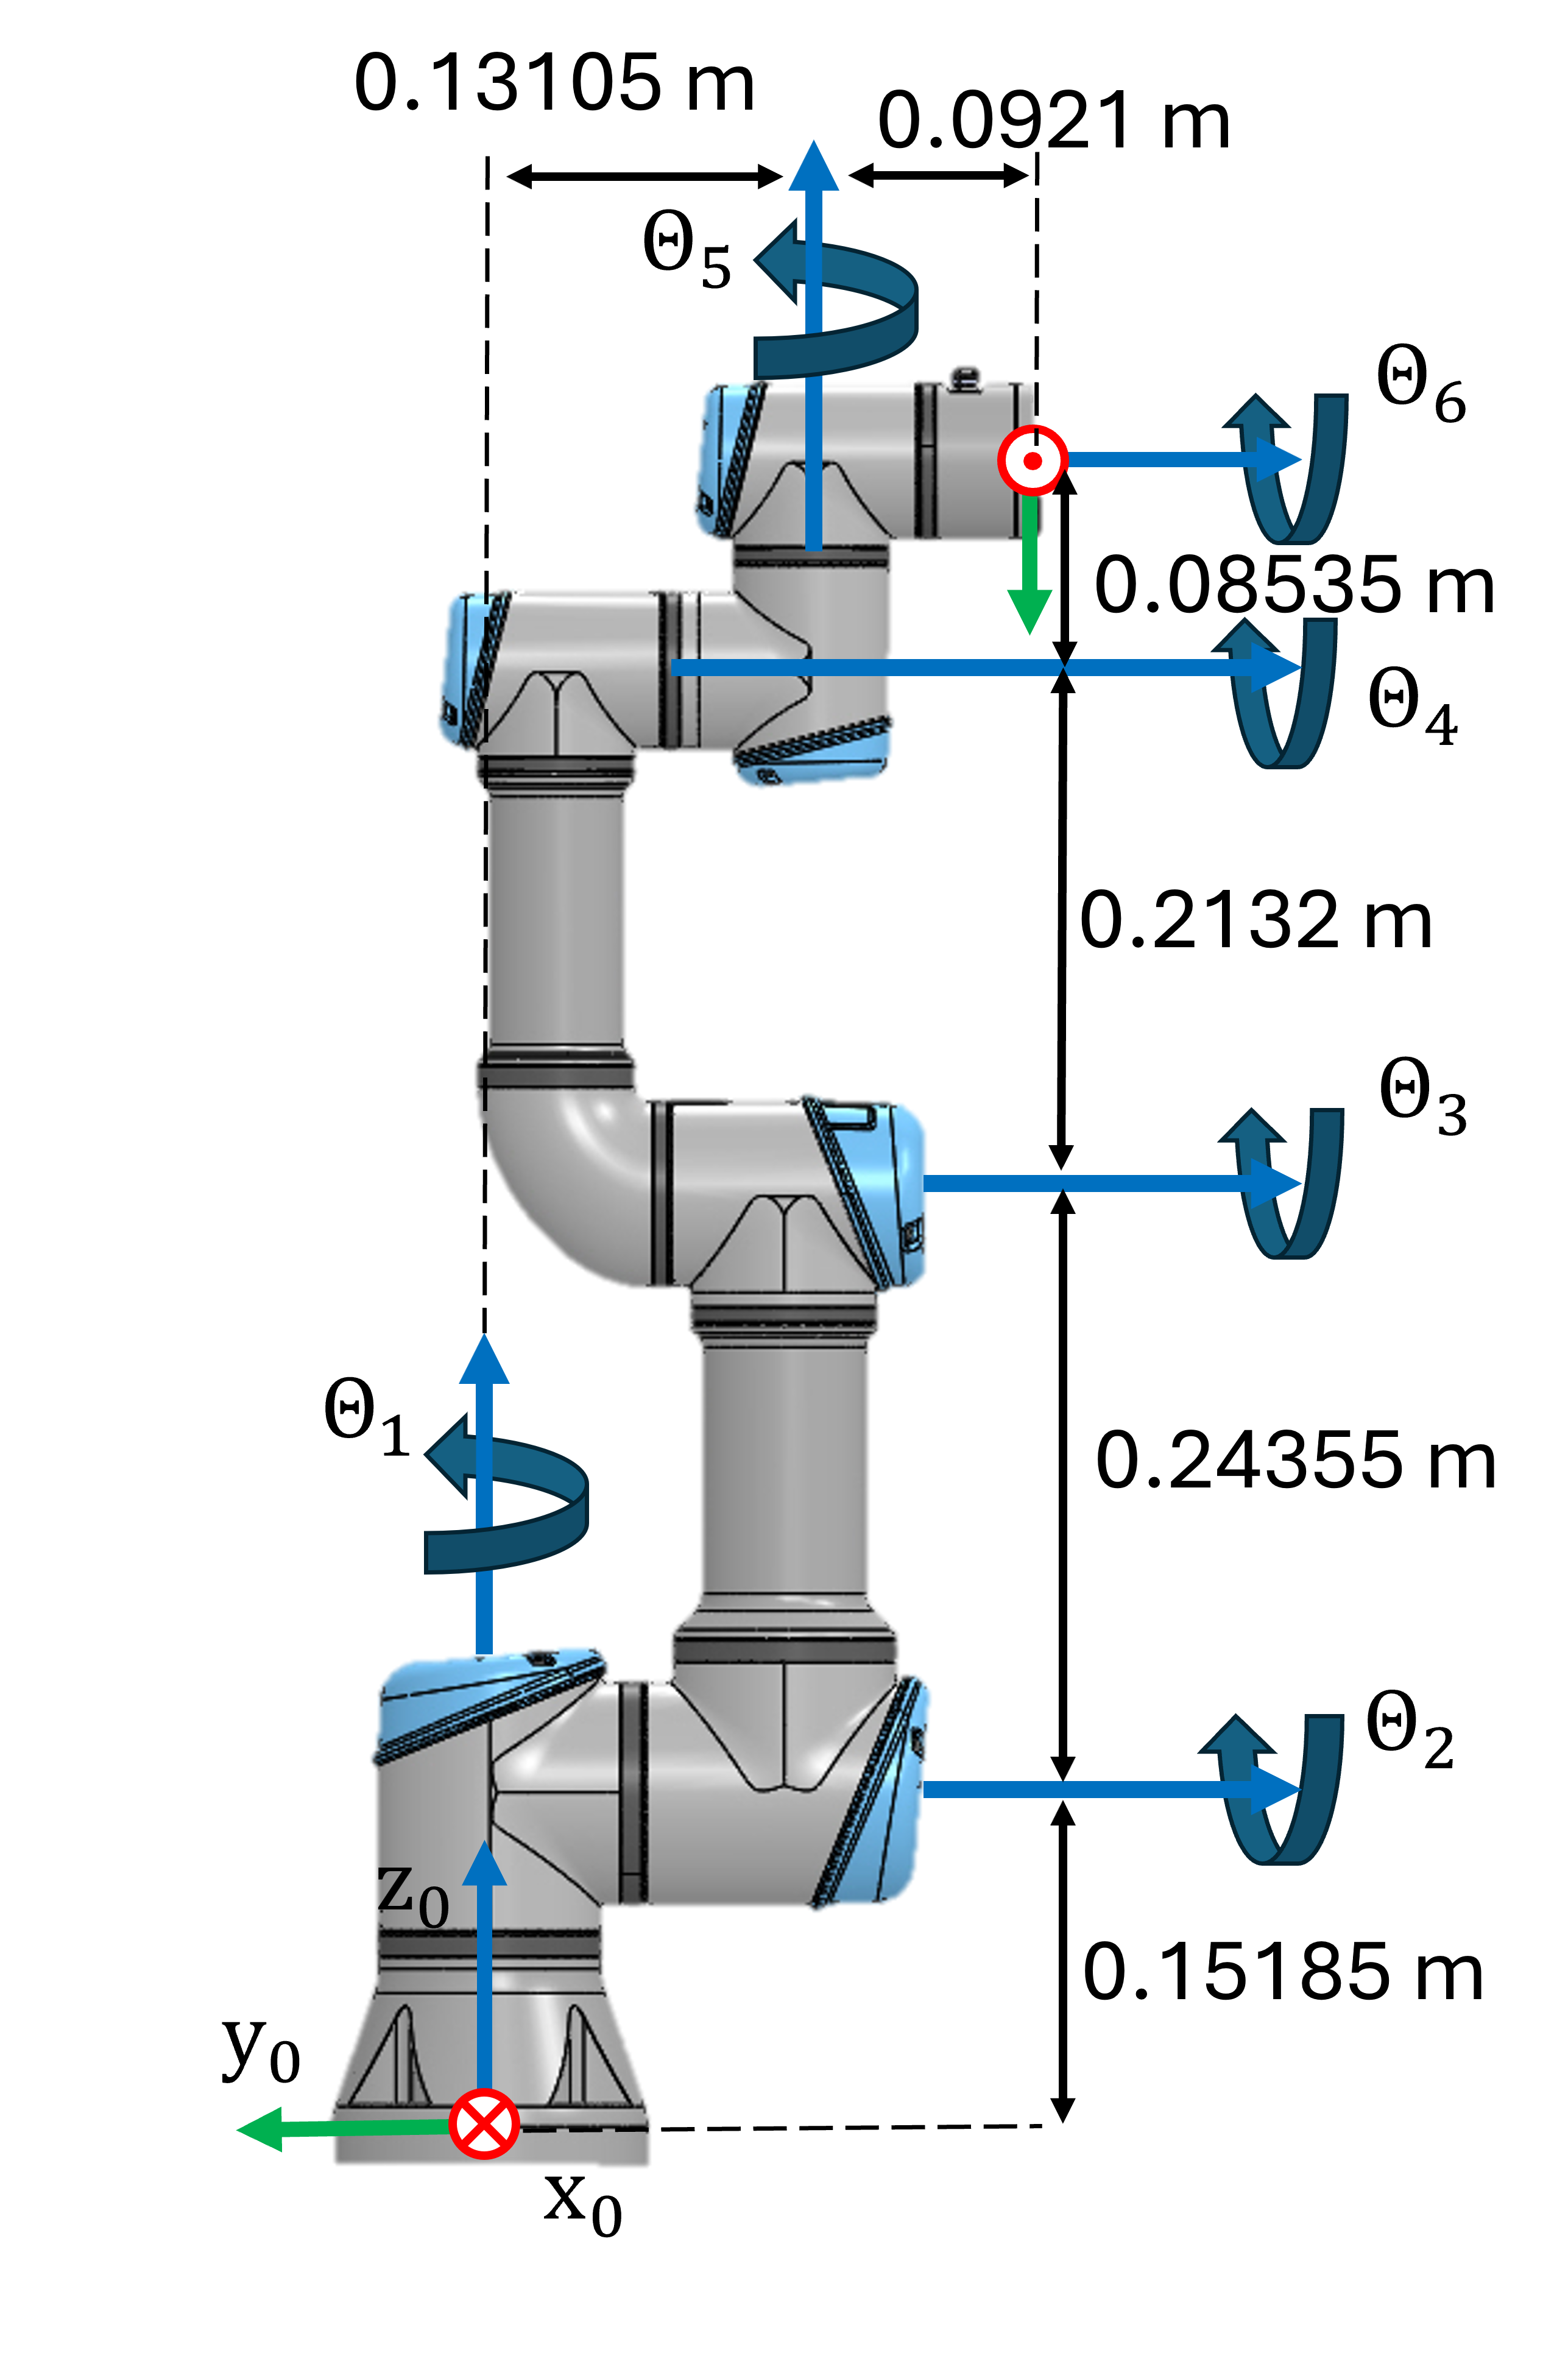

## Task 1

Setup the geometric Jacobian using the symbolic toolbox. The resulting symbolic expression should only depend on the joint states 

- Find the DH parameters and setup the Jacobian matrix. 

Use the following variables  to store your solution:

- q1 ... q6 (Real Symbolic variable for the Joint angle Theta 1-6)

- Jp (translational part of the Jacobian)

- Jtheta (rotational part of the Jacobian)

- J (complete Jacobian) 

Solve this exercise using the geometric approach! Use the function: 

- cross()

Solve this exercise without using the function: 

- dh2tf()

and without using the relation matrix $T_A \left(\Phi \right)$: 

- 
$$T_A \left(\Phi \right)=\left\lbrack \begin{array}{ccc}
0 & -\sin \left(\phi \right) & \cos \left(\phi \right)\cdot \sin \left(\theta \right)\\
0 & -\sin \left(\phi \right)\cdot \sin \left(\theta \right) & -\sin \left(\phi \right)\cdot \sin \left(\theta \right)\\
1 & \cos \left(\theta \right) & \cos \left(\theta \right)
\end{array}\right\rbrack$$


Jp = []; 
Jtheta = []; 
J = []; 

You can check your work by clicking the Run: 

 
check_exercise('3-1-1')

## Task 2

Write a function that computes the analytical jacobian (using euler angles) for a given configuration. This function takes one vector as an input: 

- configuration (q) as a row vector ($q\in {\mathbb{R}}^{6\textrm{x1}}$)

and returns the analytical jacobian and its rank at the configuration.

Use the following function name for your solution:

-  ComputeAnalyticalJacobian(q)

Solve this exercise using an analytical approach! Use the function: 

- diff()

Solve this exercise without using the relation matrix $T_A \left(\Phi \right)$: 

- 
$$T_A \left(\Phi \right)=\left\lbrack \begin{array}{ccc}
0 & -\sin \left(\phi \right) & \cos \left(\phi \right)\cdot \sin \left(\theta \right)\\
0 & -\sin \left(\phi \right)\cdot \sin \left(\theta \right) & -\sin \left(\phi \right)\cdot \sin \left(\theta \right)\\
1 & \cos \left(\theta \right) & \cos \left(\theta \right)
\end{array}\right\rbrack$$


function [Ja, Rank] = ComputeAnalyticalJacobian(q)

Ja = []; 
Rank = []; 

end

You can check your work by clicking the Run: 

 
check_exercise('3-1-2')

## Task 3

Write a function that computes the required joint velocities to achieve a specific translational motion of the endeffector for a given configuration. This function takes two vector as an input: 

- configuration (q) as a row vector ($q\in {\mathbb{R}}^{6\textrm{x1}}$)

- desired motion v, relative to the base frame,  as a row vector where $v=\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{z} 
\end{array}\right\rbrack$ 

and returns the required joint speeds as a row vector ($\dot{q} \in {\mathbb{R}}^{6\textrm{x1}}$).

Use the following function name for your solution:

-  ComputeJointSpeed(q,v)

Solve this exercise using an analytical approach! Use the function: 

- diff()

function qdot = ComputeJointSpeed(q,v)

qdot = []; 

end

You can check your work by clicking the Run: 

 
check_exercise('3-1-3')

## Task 4

Use your function from Task 3 to compute a trajectory that follows the desired motion. 

Approximate the new joint states by $q_{k+1} =q_k +\dot{q} \cdot \Delta t$ where $\dot{q}$ is the computed joint velocity for the configuration $q_k$. 

The function takes four inputs: 

- Initial Joint configuration (q)

- desired motion (v)

- timestep (dt)

- total time (T)

The function has three outputs: 

- Joint State trajectory ($q_{\mathrm{traj}} \in {\mathbb{R}}^{6\mathrm{xN}}$ where N is the amount of points in the trajectory, usually $N=\frac{T}{\Delta t}$ )

- Joint Velocity trajectory ($\dot{q_{\mathrm{traj}} } \in {\mathbb{R}}^{6\mathrm{xN}}$)

- Success, false if the manipulator hits a singularity in the desired motion dimensions (success$\in \left\lbrack \mathrm{false},\mathrm{true}\right\rbrack$). If a singularity is reached the function needs to end and send the joint states until the singularity

Use the following function name for your solution:

-  ComputeLinearTrajectory(q, v, dt, T)

function [q_traj, qdot_traj, success] = ComputeLinearTrajectory(q,v, dt, T)

end

You can check your work by clicking the Run: 

 
check_exercise('3-1-4')

You can view your trajectory in Rviz: 

  
q_example = [];
v_example = [1;0;0]; 
dt_example =0.1; 
T_example = 4; 
[q_traj_ex, ~,success_example] = ComputeLinearTrajectory(q_example,v_example,dt_example,T_example); 

if success_example
    JointStatesToRviz(q_traj_ex, 'ur3e', T_example);
else
    [~,points_until_singular,~] = size(q_traj_ex);
    Time_until_singular = points_until_singular*dt; 
    JointStatesToRviz(q_traj_ex, 'ur3e', Time_until_singular, 'Ellipsoid', true); 
end